This is some of the spray data. 

You need to find out what the two arrays below stand for by yourself.

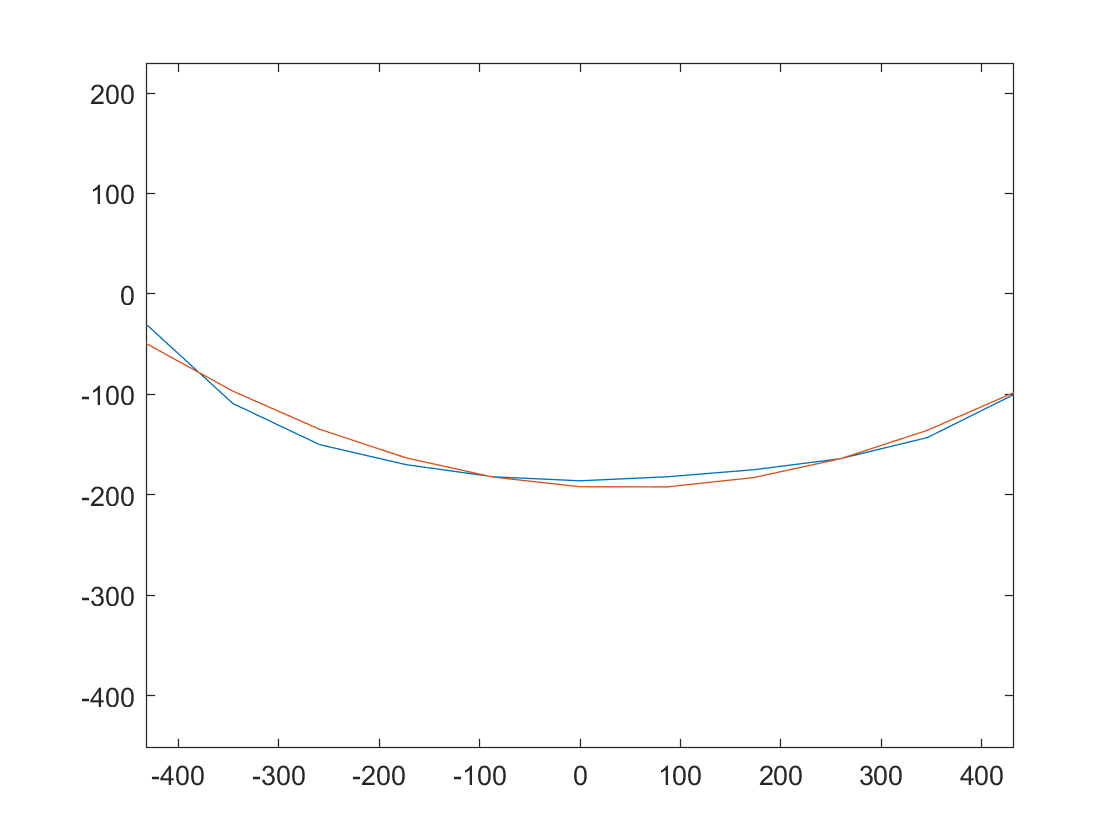

dwl=[30   109   150   170   182   186   182   175   164   143   100]; %cm 
station2=[139   130   125   118   109    93    73    45    20]'; %cm

x_unit=86.4;

x=linspace(x_unit*-5,x_unit*5,11);
P1=polyfit(x,dwl,2);
y1=polyval(P1,x);

figure(1)
plot(x,-dwl)
hold on
plot(x,-y1)
axis equal
hold off


z=linspace(23.35,130,9)

z =    23.3500   36.6813   50.0125   63.3438   76.6750   90.0062  103.3375  116.6688  130.0000


station2=fliplr(station2')

station2 =     20    45    73    93   109   118   125   130   139


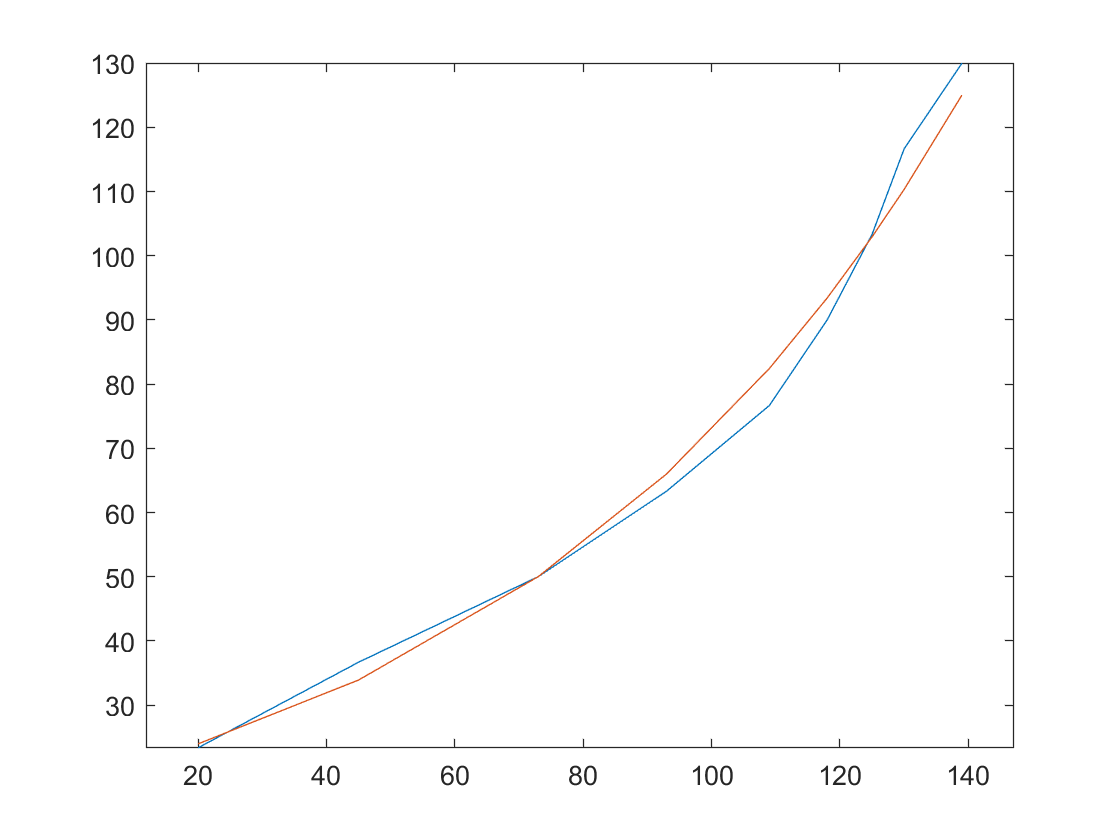


figure(2)
plot(station2,z)
P2=polyfit(station2,log(z),1);
z1=exp(polyval(P2,station2));
hold on
plot(station2,z1)
axis equal
hold off